# Free Space Propagation

clc
close all
clearvars

## Point Target RCS Signatures

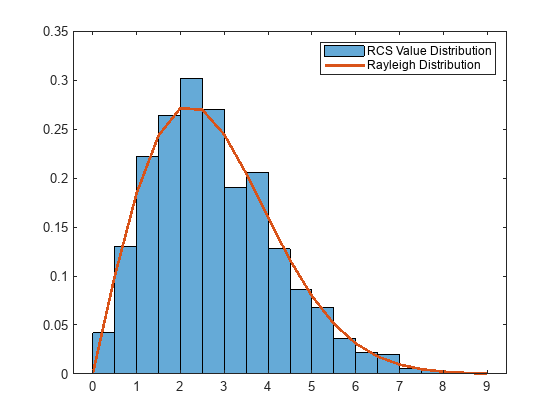

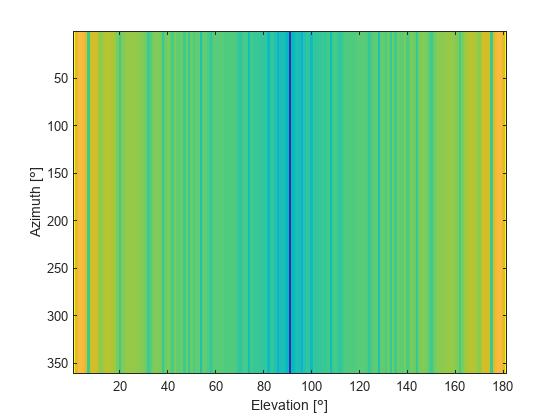

PointTarget_Soln

## Constants

c = physconst("lightspeed");
fc = 9.5e9;

## Define Radar

rdr = radarTransceiver();
rdr.Waveform = phased.RectangularWaveform("DurationSpecification","Duty cycle","DutyCycle",0.04);
rdr.ReceiveAntenna.OperatingFrequency = fc;
rdr.TransmitAntenna.OperatingFrequency = fc;
rdr.ReceiveAntenna.Sensor.ElementSpacing = freq2wavelen(fc) / 2;
rdr.TransmitAntenna.Sensor.ElementSpacing = freq2wavelen(fc) / 2;
rdr.Transmitter.PeakPower = 1e3;

mFilter = rdr.Waveform.getMatchedFilter();
% steering vector
strVec = phased.SteeringVector("SensorArray",rdr.TransmitAntenna.Sensor,"PropagationSpeed",c);
% range processor
rProcessor = phased.RangeResponse("RangeMethod","Matched filter","SampleRate",rdr.Waveform.SampleRate);

## Define Scenario

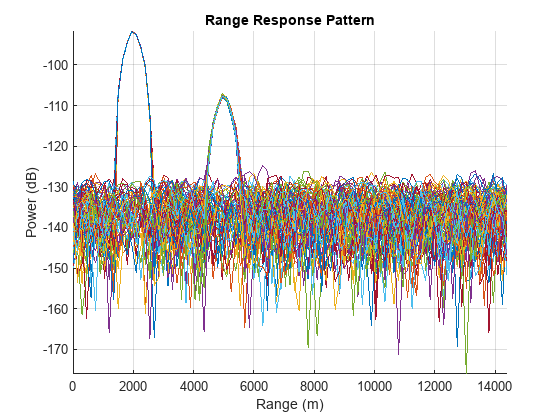

scenario = radarScenario();
radarPlatform = platform(scenario);
radarPlatform.Trajectory.Position = [0 0 500];
radarPlatform.Sensors = rdr;

targetPlatform = platform(scenario);

% Change RCS of target
% targetPlatform.Signatures{1} = sigFluc;
% set up simulation
figure
for iRange = 2000:3000:12000
    % Position target platform
    targetPlatform.Trajectory.Position = [iRange 0 500];
    for iIter = 1:50
        advance(scenario);
        recSig = receive(scenario);
        sig = recSig{1} * strVec(fc, 0);
        hold on
        plotResponse(rProcessor,sig,mFilter,"Unit","db")
        axis tight
        drawnow
    end
end